% Gitte verdier
K = 0.398; % DC-forsterkning
omega_n = 8; % Naturlig frekvens (fra fasekurven ved -90 grader)
zeta = 0.125; % Dempningsfaktor (beregnet fra toppforsterkning)

% Sett opp overføringsfunksjonen
s = tf('s');
H = K * omega_n^2 / (s^2 + 2 * zeta * omega_n * s + omega_n^2);

% Vis transferfunksjonen
disp('Overføringsfunksjon G(s):');

Overføringsfunksjon G(s):


H

H =
 
      25.47
  --------------
  s^2 + 2 s + 64
 
Continuous-time transfer function.
Model Properties


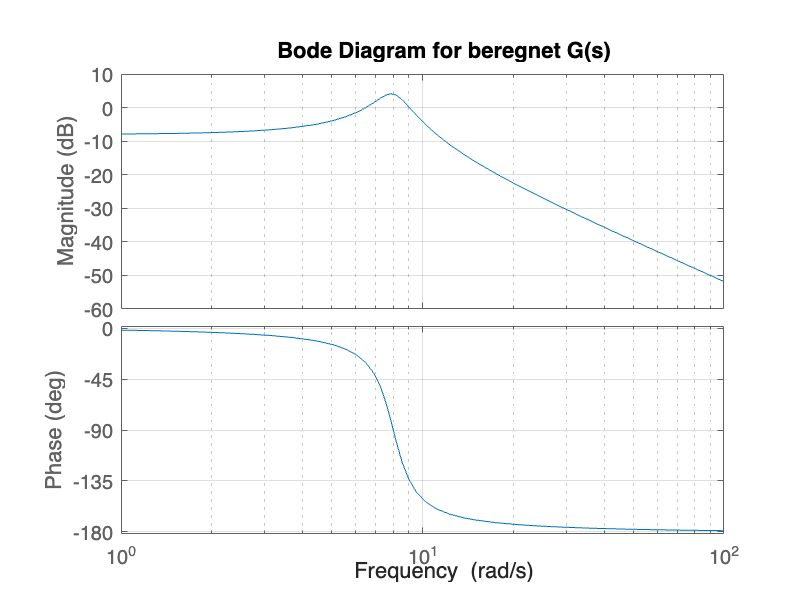


% Plot Bode-diagrammet
figure;
bode(H);
grid on;
title('Bode Diagram for beregnet G(s)');